%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% TF of 2nd-Type 2nd-Order ChargePump PLL                          %
% 2nd-Order prop-Integrator filter                                 %
%    CP-------------VCO           ---Icp/2pi--F(s)--Kv--           %
%        |                        |                   |           %
%        R1                       |--------1/N--------|           %
%        |                                                        %
%        C1                                                       %
%        |                                                        %
%       GND                                                       %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clearvars;
fstart=1e3; fstop=1e9; NumPerDec=11;
freq=LogDistrib(fstart,fstop,NumPerDec);
freq_rad=freq*(2*pi);

syms Icp R1 C1 C2 Kv N s
Z1=R1+1/(s*C1);
Fs=Z1;
Kd=Icp/(2*pi);                  % A/rad
Gs=Kd*Fs*(Kv/s*2*pi)*1/N*2*pi;  % loop TF
Hs=N*Gs/(1+Gs);                 % closed loop TF
K=Kd*Kv*2*pi*R1*1/N;            % Loop gain

fprintf('Proportional-Integrational Filter TF:\n');
pretty(simplifyFraction(Fs)); %fprintf('\n');
fprintf('Open Loop TF G(s):\n');
pretty(simplifyFraction(Gs)); %fprintf('\n');
fprintf('Open Loop Gain K:\n');
pretty(simplifyFraction(K));  %fprintf('\n');
fprintf('Closed loop TF H(s):\n');
pretty(simplifyFraction(Hs));
%fprintf('\n');
%pretty(simplifyFraction(diff(Hs,s)));

Icp_num=10e-3*2.6;         % A
R1_num=3e3;            % ohm
C1_num=20e-12 ;       % F
f0=500e6;              % VCO free running freq.Hz
fref=75e6;             % Hz
Kv_num=1e6;            % VCO gain，Hz/V
N_num=8;

tz1=C1_num*R1_num;

Gs=subs(Gs, [Icp, R1, C1, Kv, N], [Icp_num, R1_num, C1_num, Kv_num, N_num]);
Hs=subs(Hs, [Icp, R1, C1, Kv, N], [Icp_num, R1_num, C1_num, Kv_num, N_num]);
K =subs(K,  [Icp, R1, C1, Kv, N], [Icp_num, R1_num, C1_num, Kv_num, N_num]);


[num,den]=numden(Hs)

$$num = 416000\,\pi \,\left(2321137573660087875\,s+38685626227668133590597632\right)$$

$$den = 6189700196426901\,s^{2}+120699153830324569500000\,\pi \,s+2011652563838742946711076864000\,\pi$$

coef_n=double(fliplr(coeffs(num)))

coef_n =    1.0e+31 *

   0.000000303350060   5.055834332904694


coef_d=double(fliplr(coeffs(den)))

coef_d =    1.0e+30 *

   0.000000000000006   0.000000379187575   6.319792916130868


Hs_real=tf(coef_n,coef_d)


Hs_real =
 
        3.034e24 s + 5.056e31
  ----------------------------------
  6.19e15 s^2 + 3.792e23 s + 6.32e30
 
Continuous-time transfer function.



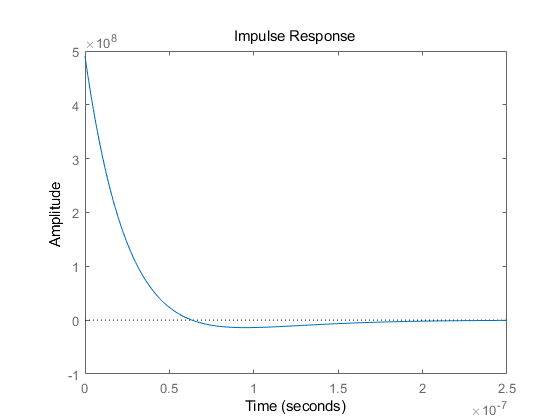

impulse(Hs_real)

for i=1:length(freq_rad)
    Gs_jw(i,1)=subs(Gs, s, 1j*freq_rad(i,1));
    Gs_mag_dB(i,1)=20*log10(abs(Gs_jw(i,1)));
    Gs_ang_deg(i,1)=angle(Gs_jw(i,1))/pi*180;
    
    Hs_jw(i,1)=subs(Hs, s, 1j*2*pi*freq_rad(i,1));
    Hs_mag_dB(i,1)=20*log10(abs(Hs_jw(i,1)));
    Hs_ang_deg(i,1)=angle(Hs_jw(i,1))/pi*180;
end
Gs_mag_dB=double(Gs_mag_dB);
Gs_ang_deg=double(Gs_ang_deg);
fprintf('Loop Gain K=%1.2g Hz\n',double(K));
fprintf('Unity Gain Freq.: %1.2g Hz\n', freq(find(Gs_mag_dB>=0, 1, 'last' )));
fprintf('Zero freq.Z=%1.2g Hz\n',1/tz1/(2*pi));
PM=Gs_ang_deg(find(Gs_mag_dB>=0, 1, 'last' ))-(-180);
fprintf('Phase Margin(deg): %1.1f\n C',PM);

figure(1);
subplot(2,1,1),semilogx(freq,Gs_mag_dB); grid on; title('Frequency Response of Magnitude G(s)');
subplot(2,1,2),semilogx(freq,Gs_ang_deg); grid on; title('Frequency Response of Phase G(s)');

figure(2);
subplot(2,1,1),semilogx(freq,Hs_mag_dB-20*log10(N_num)); grid on; title('Normalized Frequency Response of Magnitude H(s)');
subplot(2,1,2),semilogx(freq,Hs_ang_deg); grid on; title('Frequency Response of Phase H(s)');
